
% Wyciągnięcie współczynników prosto z G_z
% MATLAB zwraca je w wektorach: num (licznik) i den (mianownik)
[num, den] = tfdata(G_z, 'v');

% Wypiszmy je, żebyś wiedział co wpisać do sprawozdania/kodu C
disp('--- Współczynniki z c2d (ZOH) ---');

--- Współczynniki z c2d (ZOH) ---


disp('Mianownik (den):'); disp(den);

Mianownik (den):
    1.0000   -2.9567    2.9062   -0.9495



disp('Licznik (num):'); disp(num);

Licznik (num):
         0   -0.0079    0.0001    0.0077




% Rząd układu (ile próbek wstecz musimy pamiętać)
order = length(den) - 1; 

%% 3. REGULATOR PID (Dyskretny)
% Tutaj możemy użyć nieco łagodniejszych nastaw niż przy Eulerze,
% bo model ZOH jest dokładniejszy.
% Kp = -0.45 * 2.5;  % Trochę mocniejsze P
% Ki = -0.01;        % Minimalne I
% Kd = -0.8 * 3.0;   % Mocne D (nadal potrzebne dla wahadła)

Kp_new = Kp*100;
Kd_new = 0;
Ti_new = 9000000;

% Przeliczenie na r0, r1, r2 (Standardowy wzór PID dyskretnego)
% Ti = Kp_new / Ki;
Ki_new = Kp_new/ Ti_new;
Td = Kd_new / Kp_new;

r_0 = Kp_new * (1 + Ts/(2*Ti_new) + Td/Ts);
r_1 = Kp_new * (Ts/(2*Ti_new) - 2*Td/Ts - 1);
r_2 = (Kp_new * Td) / Ts;

fprintf('\n--- Współczynniki Regulatora Cyfrowego ---\n');


--- Współczynniki Regulatora Cyfrowego ---


fprintf('r0 = %.4f\n', r0);

r0 = -69.5233


fprintf('r1 = %.4f\n', r1);

r1 = 110.8459


fprintf('r2 = %.4f\n', r2);

r2 = -41.3231


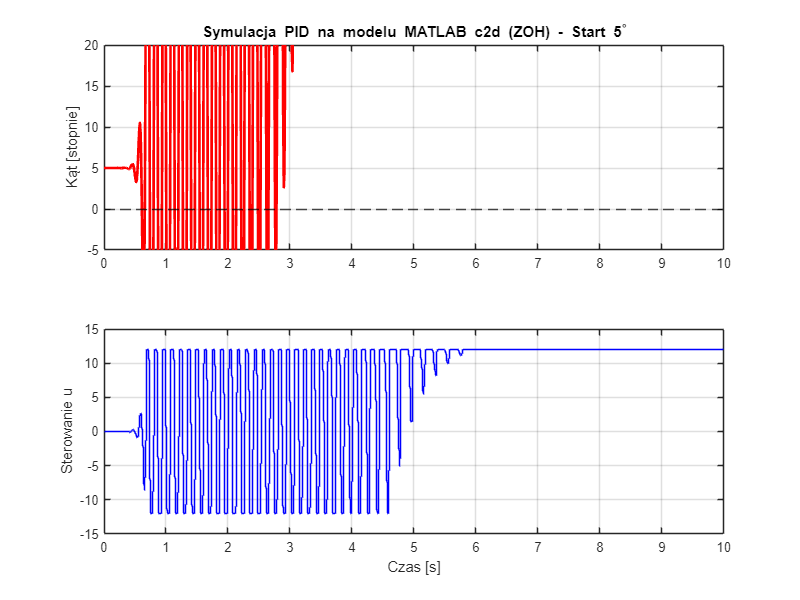


%% 4. SYMULACJA DYSKRETNA
T_sim = 10;
N = T_sim / Ts;

y = zeros(1, N);
u = zeros(1, N);
e = zeros(1, N);

% Warunek początkowy: 5 stopni
start_angle = deg2rad(5);
y(1:order+1) = start_angle;
e(1:order+1) = -start_angle;

% Ograniczenie napięcia
max_u = 12;

for k = (order+2):N
    % A. Uchyb
    e(k) = 0 - y(k-1);
    
    % B. PID (Równanie różnicowe)
    u(k) = u(k-1) + r_0*e(k) + r_1*e(k-1) + r_2*e(k-2);
    
    % Saturacja
    if u(k) > max_u, u(k) = max_u; elseif u(k) < -max_u, u(k) = -max_u; end
    
    % C. OBIEKT (Używamy współczynników z c2d!)
    % Równanie różnicowe z wektorów num/den:
    % y(k)*den(1) = -den(2)*y(k-1) - ... + num(2)*u(k-1) + ...
    
    % Automatyczna suma (działa dla rzędu 2, 3 lub 4 - uniwersalne)
    y_part = 0;
    u_part = 0;
    
    for i = 2:length(den)
        y_part = y_part - den(i) * y(k-(i-1));
    end
    for i = 2:length(num)
        u_part = u_part + num(i) * u(k-(i-1)); % Zazwyczaj num(1)=0 dla ZOH
    end
    
    y(k) = (y_part + u_part) / den(1);
end

%% 5. WYKRESY
t_vec = 0:Ts:(N-1)*Ts;

figure('Position', [100, 100, 800, 600]);
subplot(2,1,1);
plot(t_vec, rad2deg(y), 'r-', 'LineWidth', 2);
grid on;
title(['Symulacja PID na modelu MATLAB c2d (ZOH) - Start 5^\circ']);
ylabel('Kąt [stopnie]');
yline(0, 'k--');
xlim([0, 10]);
ylim([-5, 20]);

subplot(2,1,2);
stairs(t_vec, u, 'b-');
grid on;
ylabel('Sterowanie u');
xlabel('Czas [s]');

% xlim([0, 3]);
% ylim([-12, 12]);